# Digital signals generation

In this exercise you will generate a sawtooth signal and a sine signal. You will generate an analog and digital signal and you will also experiment with different parameters. Note that the Signal Processing Toolbox™ provides several functions to generate waveforms like [sin](https://uk.mathworks.com/help/signal/ref/sin.html), [square](https://uk.mathworks.com/help/signal/ref/square.html), [sawtooth](https://uk.mathworks.com/help/signal/ref/sawtooth.html), as well as the [audioOscillator](https://uk.mathworks.com/help/audio/ref/audiooscillator-system-object.html) function that implements all of these basic periodic signals and can be used as a fully tunable real-time generator.

% Clear workspace and command window
clear;
clc;

## Sawtooth signal

You can use the command [sawtooth](https://uk.mathworks.com/help/signal/ref/sawtooth.html) to generate a simple sawtooth wave.

Here, we are using a customised function to generate and visualize an analog and digital sawtooth signal. The customised fuction can can be found at the end of the script (see section *Helper Functions*).

To Do:

Experiment with the wave length (`L`) and study its effects.

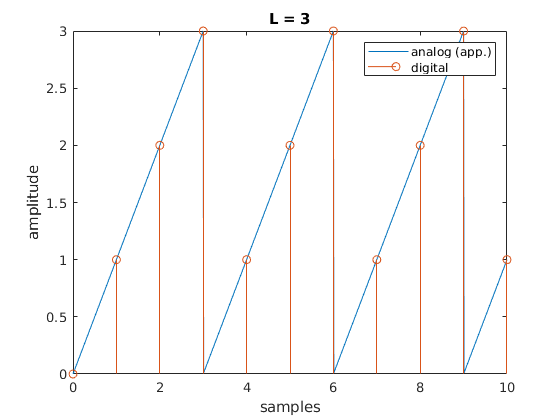


L = 3; % length of each wave
fs = 1;  % sampling frequency
D = 10;  % total duration
[signal, n] = gen_sawtooth(L, fs, D);

## Sine signal

### Unit-frequency sine signal

You can use the command [sin](https://uk.mathworks.com/help/matlab/ref/sin.html) to generate a simple sine wave.

The custom function `gen_sin` generates and visualizes an analog and digital sine signal. The code for the function can be found at the end of the script (see section *Helper functions*).

Keeping the sine frequency at 1 results in an unit-frequency sine wave.

To Do:

Experiment with the sampling frequency (`fs`) and study its effects.

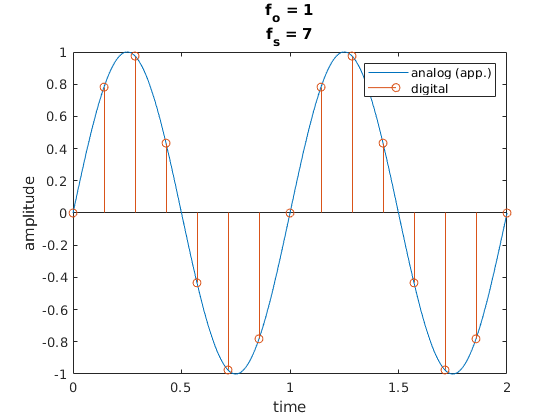

fo = 1;  % sine frequency
fs = 7; % sampling frequency
D = 2;   % duration in seconds
[signal, n] = gen_sin(fo, fs, D);  % unit frequency sine (i.e. 1 cycle per second)

### Integer-frequency sine

Typically, the sine frequency is a number unequal to 1.

Exercise:

Experiment with both frequencies (`fo` and `fs`) and study the effects. What happens when the sampling frequency `fs` is equal to or smaller than the sine frequency `fo`?

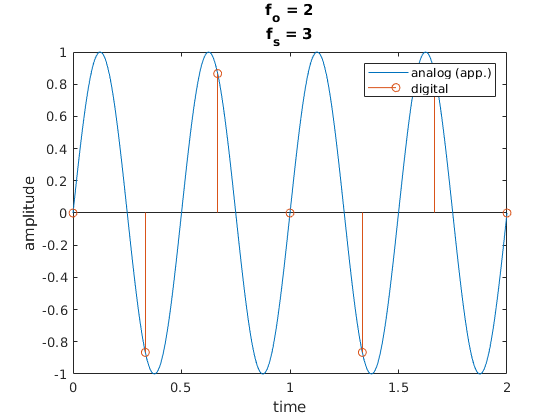

fo = 2; % sine frequency
fs = 3; % sampling frequency
D = 2;   % duration in seconds
[signal, n] = gen_sin(fo, fs, D);  % unit frequency sine (i.e. 1 cycle per second)

Note: 

When `fs` is equal or smaller than `fo`, the digital signal does not represent its analog counterpart very well. This effect also goes by the name of **aliasing**. [The Sampling Theorem or Nyquist-Shannon theorem](https://en.wikipedia.org/wiki/Nyquist%E2%80%93Shannon_sampling_theorem) defines the minimum `fs` to use in order to perfectly reconstruct the analog signal.

## Helper functions

### Generate and visualize a sawtooth signal

Samples a sawtooth signal. This can also be done by using the [sawtooth](https://uk.mathworks.com/help/signal/ref/sawtooth.html) function.

Inputs:

- `L`: lenght/duration of each tooth

- `D`: duration of total signal

- `plot_fig`: boolean flag [defaut: true]

Ouputs:

- `signal`: y-values of the digital signal

- `n`: x-values of the digital signal

function [signal, n] = gen_sawtooth(L, fs, D, plot_fig)

    if nargin<4 || isempty(plot_fig)
        plot_fig=true; 
    end
    
    n = (0:1/fs:D)';     % temporal axis
    signal = rem(n, L);  % samples
    signal(n>0 & rem(n, L)==0) = L;
    
    if plot_fig
        % Approximate analog signal by increasing the fs
        n_dense = (0:1/fs/100:D)';     % temporal axis
        signal_dense = rem(n_dense, L);     % samples
        signal_dense(n_dense>0 & rem(n_dense, L)==0) = L;
        
        figure;
        plot(n_dense, signal_dense);
        hold on;
        stem(n,signal);
        xlabel('samples'); ylabel('amplitude');
        legend('analog (app.)', 'digital');
        title(sprintf('L = %d', L));
    end
end

### Generate and visualize a sine signal

Samples a sinusoid with frequency equals to `fo`. This is achieved by using the [sin](https://uk.mathworks.com/help/matlab/ref/sin.html) function.

Inputs:

- `fo`: sine frequency

- `fs`: sampling frequency

- `D`: duration of total signal

- `plot_fig`: boolean flag [defaut: true]

Outputs:

- `signal`: y-values of the digital signal

- `n`: x-values of the digital signal


function [signal, n] = gen_sin(fo, fs, D, plot_fig)

    if nargin<4 || isempty(plot_fig)
        plot_fig=true;
    end
    
    n = (0:1/fs:D)';         % temporal axis
    signal = sin(2*pi*fo*n); % samples
    
    if plot_fig
        % Approximate analog signal by increasing the fs
        n_dense = (0:1/fs/100:D)';     % temporal axis
        signal_dense = sin(2*pi*fo*n_dense); % samples
        
        figure;
        plot(n_dense, signal_dense);
        hold on;
        stem(n,signal);
        hold off;
        xlabel('time'); ylabel('amplitude');
        legend('analog (app.)', 'digital');
        title(sprintf('f_o = %g\nf_s = %g', fo, fs));
        
    end
end